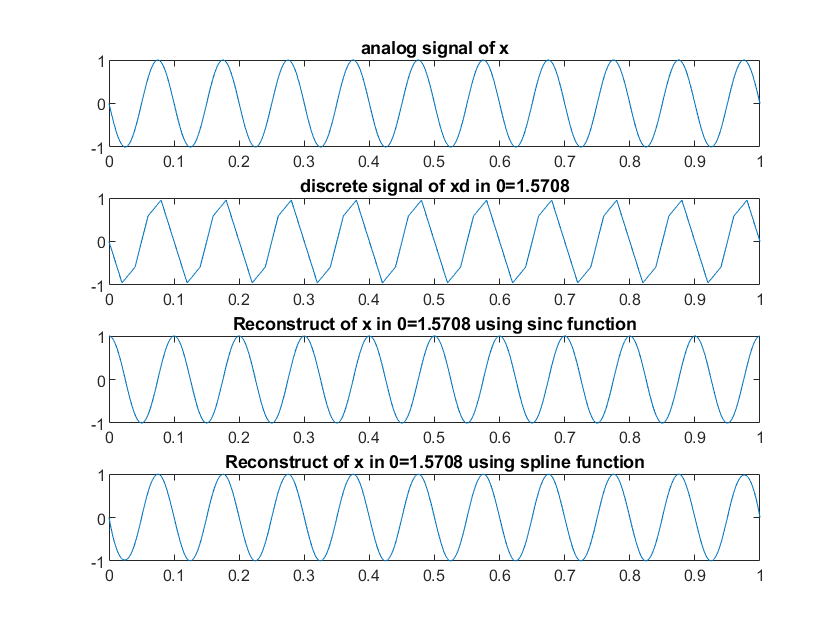

% in changing of Fs, when we reconstruct the signal using spline
% it's find analog signal with more accurately
t=0:0.001:1;
% theta=0;
% theta=pi/6;
% theta=pi/4;
% theta=pi/3;
theta=pi/2;
xa=cos(20*pi*t+theta);
subplot(4,1,1)
plot(t,xa)
title('analog signal of x')
% prb 3.17.1
fs=50;
ts=1/fs;
n=0:50;
xd=cos(20*pi*ts*n+theta);
subplot(4,1,2)
plot(n*ts,xd)
title(strcat('discrete signal of xd in 0= ',num2str(theta)))

% prb 3.17.2 reconstruct using sinc function
yrs=xd*sinc(fs*(ones(length(n),1)*t-(ts*n)'*ones(1,length(t))));
subplot(4,1,3)
plot(t,ya)
title(strcat('Reconstruct of x in 0= ',num2str(theta),' using sinc function'))
% prb 3.17.3 Reconstruct using cubic spline
yrsp=spline(n*ts,xd,t);
subplot(4,1,4)
plot(t,yrsp)
title(strcat('Reconstruct of x in 0= ',num2str(theta),' using spline function'))


errorsinc=max(abs(xa-yrs))

errorsinc = 0.1269

errorsp=max(abs(xa-yrsp))

errorsp = 0.0662